# Eksamen 2021 forår

clc; clear;
CP = py.importlib.import_module("CoolProp.CoolProp");



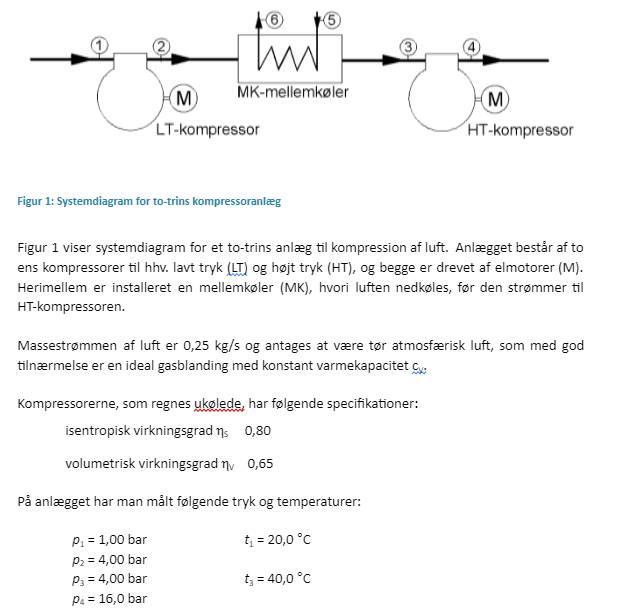

% enhedshåndtering
bar = 1e5;
t0 = 273.15;


% data
qm_luft = 0.25;
eta_s = 0.8;
eta_v = 0.65;

% tryk og temps
p1 = 1*bar;     t1 = 20+t0;
p2 = 4*bar;
p3 = p2;        t3 = 40+t0

t3 = 313.1500

p4 = 16*bar

p4 = 1600000


% Opgave a)
stof = "air";
rho1 = CP.PropsSI("D","T",t1, "P", p1, stof)

rho1 = 1.1888

qv1 = qm_luft/rho1

qv1 = 0.2103


rho3 = CP.PropsSI("D","T",t3, "P", p3, stof)

rho3 = 4.4534

qv3 = qm_luft/rho3

qv3 = 0.0561

% for den første kompressor
qvs_1 = nan;
qvs_1 = Slagvolumenstrom(eta_v,qv1,qvs_1)

Formlen for slagvolumenstrømmen


$$eq = \eta_{V}=\frac{q_{\mathrm{v1}}}{q_{\mathrm{vs}}}$$

---------------------------------------------------
Der løses for: q_vs


$$sol = \frac{q_{\mathrm{v1}}}{\eta_{V}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
             Variabel              Størrelse    Enhed 
    ___________________________    _________    ______

    "Volumetrisk virkningsgrad"       0.65      "-"   
    "Indsuget volumenstrøm"         0.2103      "m3/s"
    "Slagvolumenstrøm"              0.3235      "m3/s"



$$qvs\_1 = 0.3235$$


% for den anden kompressor
qvs_3 = nan;
qvs_3 = Slagvolumenstrom(eta_v,qv3,qvs_3)

Formlen for slagvolumenstrømmen


$$eq = \eta_{V}=\frac{q_{\mathrm{v1}}}{q_{\mathrm{vs}}}$$

---------------------------------------------------
Der løses for: q_vs


$$sol = \frac{q_{\mathrm{v1}}}{\eta_{V}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
             Variabel              Størrelse    Enhed 
    ___________________________    _________    ______

    "Volumetrisk virkningsgrad"       0.65      "-"   
    "Indsuget volumenstrøm"         0.0561      "m3/s"
    "Slagvolumenstrøm"              0.0864      "m3/s"



$$qvs\_3 = 0.08636$$

cp1 = CP.PropsSI("C","T",t1, "P", p1, stof);
cv1 = CP.PropsSI("O","T",t1, "P", p1, stof);
kap1 = cp1/cv1

kap1 = 1.4019


t2s = nan;
t2s = T2s_UdFraEksponent(t2s, t1, p1, p2, kap1);

Energiligningen opstilles:


$$eq = T_{\mathrm{is}}=T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Der løses for: T_is


$$sol = T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
           Variabel            Størrelse    Enhed
    _______________________    _________    _____

    "Isentropisk temp. t2s"      436.2      "K"  
    "t1"                         293.2      "K"  
    "p1"                         1e+05      "Pa" 
    "p2"                         4e+05      "Pa" 
    "Isentrop eksponent"           1.4      "-"  




t2 = nan;
t2 = Isentrop_Virkningsgrad(eta_s, t1, t2, t2s, "temp","komp");

Følgende formel er brugt
---------------------------------------------------
De korrekte temperatur-navne fremgår ikke altid af formlen
I tabellen nedenfor fremgår de med korrekt navn samt værdi og enhed


$$\frac{T_{\mathrm{2s}}-T_{1}}{T_{2}-T_{1}}=\eta_{S}$$

---------------------------------------------------
Der løses for: T_2


$$sol = \frac{T_{\mathrm{2s}}-T_{1}+T_{1}\,\eta_{S}}{\eta_{S}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
            Variabel            Størrelse    Enhed
    ________________________    _________    _____

    "Isentrop virkningsgrad"     0.8          "-" 
    "t1"                         293.15       "K" 
    "t2"                         471.98       "K" 
    "t2s"                        436.22       "K" 



T2_celsius = t2 - t0

$$T2\_celsius = 198.83461099816486239433288574219$$



cp3 = CP.PropsSI("C","T",t3, "P", p3, stof);
cv3 = CP.PropsSI("O","T",t3, "P", p3, stof);
kap2 = cp3/cv3

kap2 = 1.4058


t4s = nan;
t4s = T2s_UdFraEksponent(t4s, t3,p3,p4,kap2);

Energiligningen opstilles:


$$eq = T_{\mathrm{is}}=T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Der løses for: T_is


$$sol = T_{\mathrm{im1}}\,{\left(\frac{p_{i}}{p_{\mathrm{im1}}}\right)}^{\frac{\kappa -1}{\kappa }}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
           Variabel            Størrelse    Enhed
    _______________________    _________    _____

    "Isentropisk temp. t4s"       467.2     "K"  
    "t3"                          313.2     "K"  
    "p3"                          4e+05     "Pa" 
    "p4"                        1.6e+06     "Pa" 
    "Isentrop eksponent"            1.4     "-"  




t4 = nan;
t4 = Isentrop_Virkningsgrad(eta_s, t3, t4, t4s, "temp","komp");

Følgende formel er brugt
---------------------------------------------------
De korrekte temperatur-navne fremgår ikke altid af formlen
I tabellen nedenfor fremgår de med korrekt navn samt værdi og enhed


$$\frac{T_{\mathrm{2s}}-T_{1}}{T_{2}-T_{1}}=\eta_{S}$$

---------------------------------------------------
Der løses for: T_2


$$sol = \frac{T_{\mathrm{2s}}-T_{1}+T_{1}\,\eta_{S}}{\eta_{S}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
            Variabel            Størrelse    Enhed
    ________________________    _________    _____

    "Isentrop virkningsgrad"     0.8          "-" 
    "t3"                         313.15       "K" 
    "t4"                         505.76       "K" 
    "t4s"                        467.24       "K" 



T4_celsius = t4 - t0

$$T4\_celsius = 232.61114200111478567123413085938$$

cp2 = CP.PropsSI("C","T", double(t2), "P", p2, stof);
cp4 = CP.PropsSI("C","T", double(t4), "P", p4, stof);

h1 = t1 * cp1;
h2 = t2 * cp2;
h3 = t3 * cp3;
h4 = t4 * cp4;

phi_lt = nan;
phi_ht = nan;

massestrom_all(phi_lt, qm_luft,h1,h2)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

De korrekte entalpi-navne fremgår ikke altid af formlen
I tabellen nedenfor fremgår de med korrekt navn samt værdi og enhed
---------------------------------------------------
Der løses for: Phi


$$sol = h_{4}\,q_{\mathrm{mR}}-h_{1}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse    Enhed 
    ____________    _________    ______

    "Phi "          47374.24     "W"   
    "Massestrøm"    0.25         "kg/s"
    "h1"            294944.65    "J/kg"
    "h2"            484441.6     "J/kg"



$$ans = 47374.2375$$

massestrom_all(phi_ht, qm_luft,h3,h4)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

De korrekte entalpi-navne fremgår ikke altid af formlen
I tabellen nedenfor fremgår de med korrekt navn samt værdi og enhed
---------------------------------------------------
Der løses for: Phi


$$sol = h_{4}\,q_{\mathrm{mR}}-h_{1}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse    Enhed 
    ____________    _________    ______

    "Phi "          52065.05     "W"   
    "Massestrøm"    0.25         "kg/s"
    "h3"            316650.19    "J/kg"
    "h4"            524910.39    "J/kg"



$$ans = 52070.0$$

phi_mellemkoler = nan;

phi_mellemkoler = massestrom_all(phi_mellemkoler,qm_luft,h2,h3)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

De korrekte entalpi-navne fremgår ikke altid af formlen
I tabellen nedenfor fremgår de med korrekt navn samt værdi og enhed
---------------------------------------------------
Der løses for: Phi


$$sol = h_{4}\,q_{\mathrm{mR}}-h_{1}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse    Enhed 
    ____________    _________    ______

    "Phi "          41947.85     "W"   
    "Massestrøm"    0.25         "kg/s"
    "h2"            484441.6     "J/kg"
    "h3"            316650.19    "J/kg"



$$phi\_mellemkoler = 41950.0$$


h1_vand = CP.PropsSI("H","T", 21 + t0, "Q",0,"water");
h2_vand = CP.PropsSI("H","T", 30 + t0, "Q",0,"water");

qmr_vand = nan;
qmr_vand = massestrom_all(phi_mellemkoler,qmr_vand,h1_vand,h2_vand)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

De korrekte entalpi-navne fremgår ikke altid af formlen
I tabellen nedenfor fremgår de med korrekt navn samt værdi og enhed
---------------------------------------------------
Der løses for: q_mR


$$sol = -\frac{\Phi }{h_{1}-h_{4}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse    Enhed 
    ____________    _________    ______

    "Phi "          41947.85     "W"   
    "Massestrøm"    1.11         "kg/s"
    "h1_vand"       88098.3      "J/kg"
    "h2_vand"       125733.97    "J/kg"



$$qmr\_vand = 1.115$$

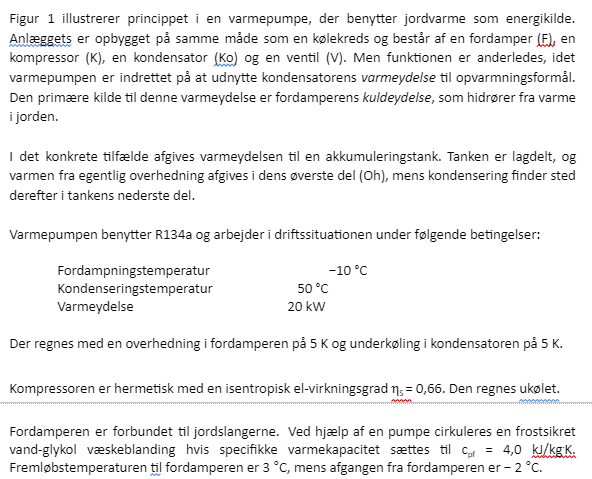

% Opgave a) direkte i coolpack opg til bilag

% Opgave b)
hs = [395.678 456 263.712 264]*1e3;
phi = 20e3; % kW til W

h1 = hs(1);
h2 = hs(2);
h3 = hs(3);
h4 = hs(4);

qm_r134a = nan;
qm_r134a = massestrom_all(phi, qm_r134a, h2, h3) % fordi det er varmestrøm, er det kondensatoren vi kigger på

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

De korrekte entalpi-navne fremgår ikke altid af formlen
I tabellen nedenfor fremgår de med korrekt navn samt værdi og enhed
---------------------------------------------------
Der løses for: q_mR


$$sol = -\frac{\Phi }{h_{1}-h_{4}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse     Enhed 
    ____________    __________    ______

    "Phi "               20000    "W"   
    "Massestrøm"           0.1    "kg/s"
    "h2"              4.56e+05    "J/kg"
    "h3"            2.6371e+05    "J/kg"



$$qm\_r134a = 0.104$$

P_aksel_komp = nan;

P_aksel_komp = massestrom_all(P_aksel_komp,qm_r134a,h1,h2)

Energiligningen opstilles:


$$eq = \Phi +q_{\mathrm{mR}}\,\left(h_{1}-h_{4}\right)=0$$

De korrekte entalpi-navne fremgår ikke altid af formlen
I tabellen nedenfor fremgår de med korrekt navn samt værdi og enhed
---------------------------------------------------
Der løses for: Phi


$$sol = h_{4}\,q_{\mathrm{mR}}-h_{1}\,q_{\mathrm{mR}}$$

---------------------------------------------------
Resultat og brugte værdier ses i nedenstående skema
      Variabel      Størrelse    Enhed 
    ____________    _________    ______

    "Phi "          6274.13      "W"   
    "Massestrøm"    0.1          "kg/s"
    "h1"            395678.0     "J/kg"
    "h2"            456000.0     "J/kg"



$$P\_aksel\_komp = 6274.0$$

% effektfaktor
epsilon = phi/P_aksel_komp

$$epsilon = 3.1876927157558714020510051333941$$